syms x
sys = tf(1,[1 2 1]);
s = stepinfo(sys, "SettlingTimeThreshold", 0.05);
w = s.TransientTime/0.1;
sys = ss(tf(1, [1 2*w w^2]));
sys = ss(canon(sys, 'companion').A', [0;1], [1,0],0);
A_m = sys.A;
B_m = [0;1];
C_m = [1,0];

A = [3 -1; -2 2];
B = [8; 8];
C = [1, 0];
M = sylvester(A, -A_m, B*[1,1]);
K = [1,1]*inv(M);

A_0_f = [0, 1; -0.16, -sqrt(0.32)];

P = lyap((A - B*K)', -eye(2));

global SAVE_EXT;
SAVE_EXT = "png";% figure saving conf (png, eps, etc...)
mkdir figs

function plot_state(out)
    h = figure();
    sgtitle("State", 'Interpreter', 'latex')
    subplot(2,1,1)
    title("First component")
    hold on
    plot(out.x.time, out.x.data(:,1), 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-')
    legend(["$x_1$"], 'Interpreter', 'latex', 'Location', 'southeast')
    grid
    hold off
    subplot(2,1,2)
    title("Second component")
    hold on
    plot(out.x.time, out.x.data(:,2), 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-')
    legend(["$x_2$"], 'Interpreter', 'latex', 'Location', 'northeast')
    grid
    hold off
end

function plot_u(out)
    h = figure();
    title("Control signal")
    hold on
    plot(out.u.time, out.u.data(:,1), 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-')
    grid
    hold off
end

function task3(exp_name)
    global SAVE_EXT;
    simIn = Simulink.SimulationInput("lab11_test");  % Read model
    simIn = setModelParameter(simIn, 'StopTime', '100000');
    sim_res = sim(simIn);
    plot_state(sim_res)
    exportgraphics(gcf, "figs/" + exp_name + "_state." + SAVE_EXT)
    plot_u(sim_res)
    exportgraphics(gcf, "figs/" + exp_name + "_u." + SAVE_EXT)
end

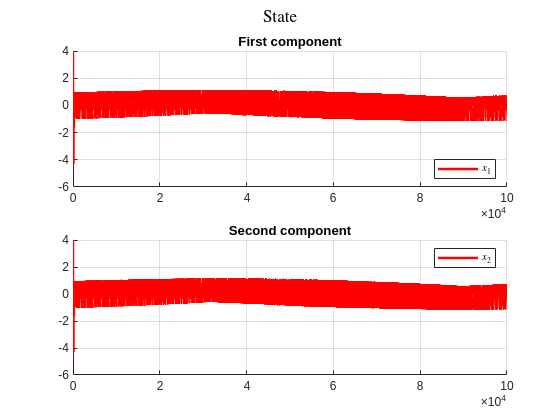

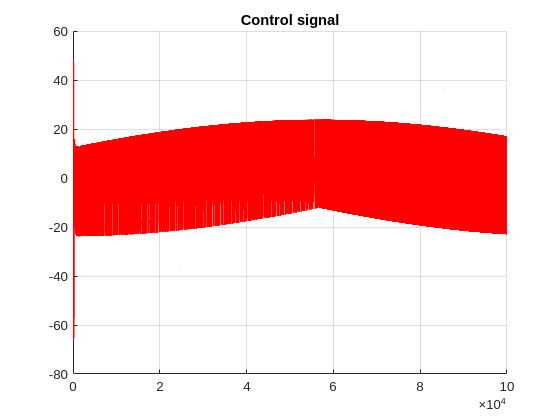

gamma = 100;
task3("gamma_100")

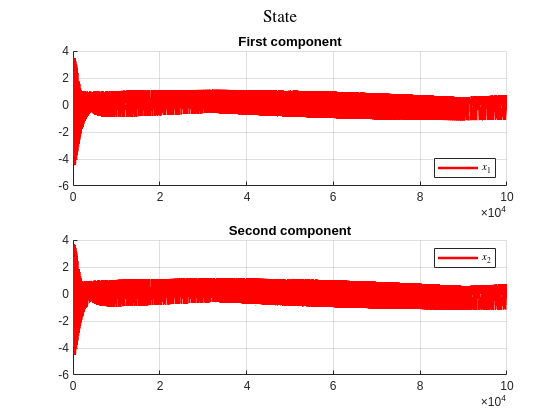

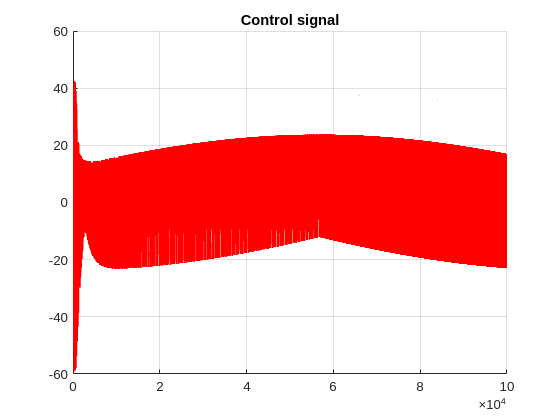

gamma = 10;
task3("gamma_10")